# Ideal case code

## Import data (from camera 1)

%%% Imports data
Dataset = 'Ideal Case';
Camera = 'cam1_1.mat';

camData = importCamData(Dataset,Camera);


## Camera 1

### Shows uncropped and cropped frame in colour

%%% Shows uncropped and cropped frame in colour
frame = 1

frame = 1

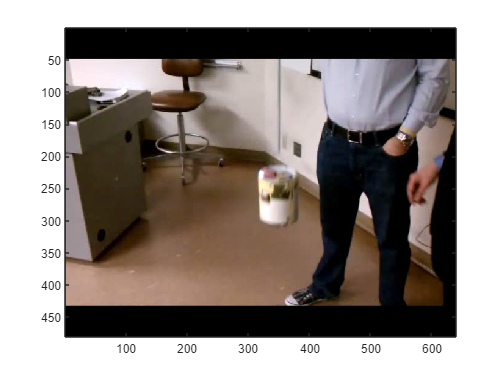


camImage = image(camData.vidFrames1_1(:,:,:,frame));

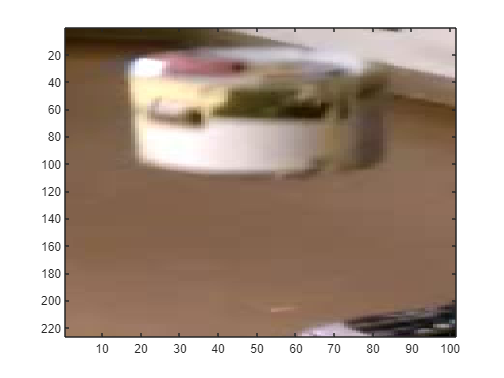

width = 300:400;
height = 200:425;
croppedFrame = camData.vidFrames1_1(height,width,:,frame);
croppedFrame1 = camData.vidFrames1_1(height,width,:,1);
camImageCropped = image(croppedFrame);

### Shows frame of grayscale image

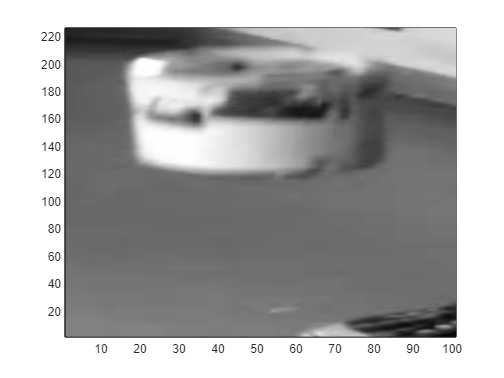

%%% Shows a frame from any camera as a grayscale colourmap (to locate
%%% locations of particular points

%%% Modified from: Data-Driven Modeling & Scientific Computation: 
%%% Methods for Complex Systems & Big Data 
%%% by J. NATHAN KUTZ


a = flipud( double( rgb2gray( camData.vidFrames1_1(height,width,:,1) )));
% a = flipud( double( rgb2gray( camData_2.vidFrames2_1(height_2,width_2,:,1) )));
% a = flipud( double( rgb2gray( camData_3.vidFrames3_1(height_3,width_3,:,1) )));

% x = 1:640;
% y = 1:480;
% [X,Y]=meshgrid(x,y);
% pcolor(X,Y,a)
pcolor(a)
shading interp
colormap("gray")

% set(gca,'Xtick',[],'Ytick',[],'Ztick',[])


### Finds and shows cap pixels (using both methods)

%%% Finds and shows cap pixels
x = 22;
y = 197;


r = croppedFrame1(end-y,x,1)

r = uint8
249

g = croppedFrame1(end-y,x,2)

g = uint8
255

b = croppedFrame1(end-y,x,3)

b = uint8
253

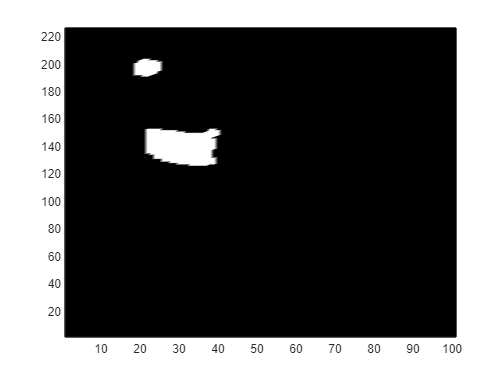


d = 20;
cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));

pcolor(flipud(cap_Pixels))
shading interp
colormap("gray")

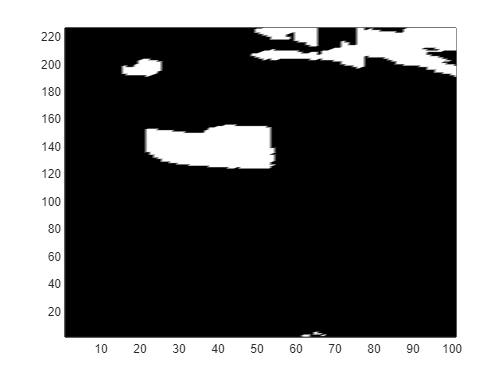


cap_Pixels_2 = getCapPixelsBright(croppedFrame,d);

pcolor(flipud(cap_Pixels_2))
shading interp
colormap("gray")

### Finds x and y coordinate of average of cap pixels

%%% Finds x and y coordinate of average of cap pixels
bounds = Boundaries(cap_Pixels)

bounds = 202

[top,bottom,left,right] = Boundaries(cap_Pixels)

top = 202

bottom = 125

left = 19

right = 40


[x,y] = centre(top,bottom,left,right)

x = 29.5000

y = 163.5000

[x_avg,y_avg] = centre_avg(cap_Pixels)

x_avg = 29.4735

y_avg = 147.1918

### Finds position of cap and stores it into a vector

%%% Finds position of cap and stores it into a vector
numFrames = size(camData.vidFrames1_1(1,1,1,:),4);
width = 300:400;
height = 200:425;
croppedFrame1 = camData.vidFrames1_1(height,width,:,1);

x = 22;
y = 197;
d = 20;

X_0 = zeros(1,numFrames);
Y_0 = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData.vidFrames1_1(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X_0(i) = x_avg;
    Y_0(i) = y_avg;
end

X_0

X_0 =    29.4735   29.3326   29.2623   29.3360   29.3306   29.3306   29.3306   29.3306   32.9406   34.8804   34.9306   33.2451   33.2544   32.2563   32.2579   31.6225   30.8534   30.8344   30.5163   30.5209   30.0099   30.0476   28.8054   28.7107   28.7218   31.9036   32.0434   33.7573   33.7162   34.9244   34.3037   34.3088   31.3724   31.4217   27.3066   27.3789   27.8837   28.3228   28.3516   28.6404   28.6303   28.8011   28.7721   29.5556   29.6714   29.6776   30.2056   30.2343   33.3731   33.2343


Y_0

Y_0 =   147.1918  147.2141  147.5656  147.4338  147.4796  147.4796  147.4796  147.4796  151.6327  152.6360  152.7326  148.9275  148.9941  141.4727  141.4570  131.9117  116.8147  116.8989  100.9465  100.9907   84.8251   84.5589   67.6865   51.6336   51.7355   40.2081   40.0714   34.5528   34.6464   33.1113   36.6370   36.7765   43.5944   43.4848   53.1977   53.1083   68.2382   86.0000   85.8732  102.0758  102.0196  116.8925  117.0027  129.5455  140.5610  140.6612  143.7684  143.9349  149.6307  149.2838


### Plots X and Y for camera 1

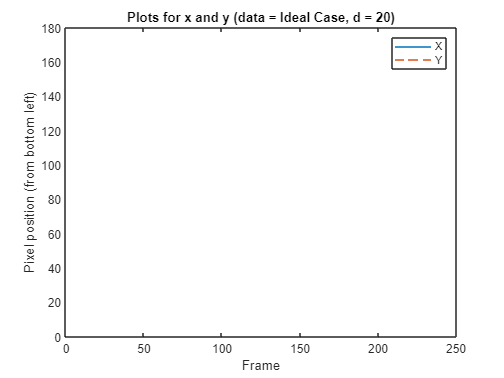

%%% Plots X and Y
plot(X_0)
title('Plots for x and y (data = Ideal Case, d = 20)')
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y_0,'--')
legend('X','Y')
hold off

### Finds and plots X and Y for camera 1 for any d (with function that uses initial position)

%%% Finds and plots X and Y for any d (with function)
width = 300:400;
height = 200:425;
x = 22;
y = 197;
d1 = 10;

[X_11,Y_11] = getXY(camData.vidFrames1_1,width,height,x,y,d1)

X_11 =    28.0784   28.0784   28.1318   28.2011   28.1532   28.1532   28.1532   28.1532   30.2137   31.9418   32.0892   31.0878   31.1193   31.4181   31.4246   30.5902   30.0307   30.0245   29.8306   29.8599   29.1504   29.1686   27.6627   27.9253   27.9385   28.5907   28.5698   32.5597   32.3045   33.7926   33.3434   33.4797   27.2579   27.2534   26.2489   26.3884   27.0581   27.1688   27.1423   27.2231   27.2181   27.4888   27.4647   28.4963   28.5360   28.5588   29.6096   29.6054   31.1009   31.2236


Y_11 =   148.4006  148.4006  149.0774  149.0517  149.1763  149.1763  149.1763  149.1763  150.2744  150.4127  150.4961  148.7394  148.7784  143.2655  143.4665  133.5413  119.7853  119.7615  104.6710  104.6352   88.7970   88.5632   72.4960   53.8921   53.8648   40.5367   40.5659   36.2164   35.9436   33.5953   38.4264   38.0074   43.7873   43.7873   57.6751   57.1612   72.7842   90.8987   90.8536  107.3017  107.5021  121.8843  122.0335  133.9142  144.1906  144.4559  148.4555  148.4286  149.8012  149.8066


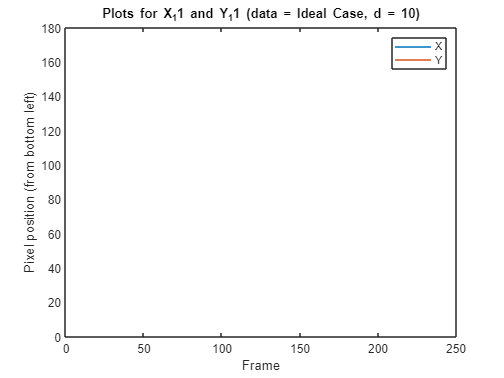

% X_11 = X_11+width(1);
% Y_11 = Y_11+height(1);

plotXY(X_11,Y_11,d1,Dataset)

### Finds and plots X and Y for camera 1 for any d (with function that uses brightness)

%%% Finds and plots X and Y for any d (with function)
width = 300:400;
height = 200:425;
d2 = 50;

[X_12,Y_12] = getXYBright(camData.vidFrames1_1,width,height,d2)

X_12 =    45.0836   45.4077   45.9478   46.3309   46.3171   46.3507   46.3171   46.3507   44.8744   44.4832   44.4132   45.7679   45.7884   46.3547   46.3535   45.3389   45.1482   44.9661   44.4330   44.5662   43.6248   43.5851   43.8722   44.1472   43.9736   42.6394   42.5773   41.7956   41.7989   42.5135   42.7434   42.8783   43.3478   43.3326   43.6908   43.5473   43.4420   44.3726   44.5168   45.7160   45.7339   44.2574   43.8650   46.7425   48.0629   47.8728   46.3709   46.3290   44.6443   44.4859


Y_12 =   139.2498  140.0775  140.7959  141.0343  141.0733  141.0577  141.0733  141.0577  138.6531  137.5131  137.4104  138.1269  138.3597  133.4505  133.1377  127.6197  122.6278  122.4928  114.8908  115.0978  107.2657  107.1183  100.6009   95.0681   94.6229   88.7375   88.5611   84.9842   84.9265   81.1585   83.5758   83.6688   90.1505   90.2382   96.1513   96.2813  102.1296  109.1599  109.2096  118.0716  117.9539  124.4111  123.8266  131.0681  138.7052  138.1392  141.2370  141.0755  140.0702  139.8135


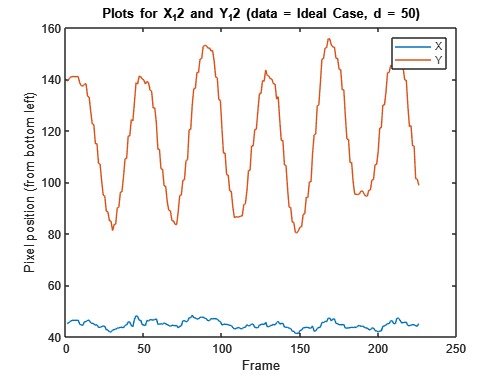


plotXY(X_12,Y_12,d2,Dataset)

## Camera 2

### Imports data

%%% Imports data from second camera
Camera_2 = 'cam2_1.mat';

camData_2 = importCamData(Dataset,Camera_2);


### Shows uncropped and cropped frame in colour

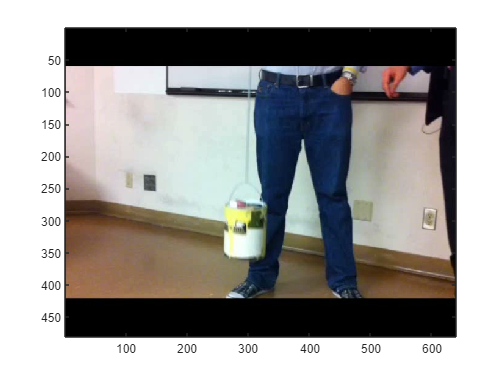

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_2 = 1;

camImage_2 = image(camData_2.vidFrames2_1(:,:,:,frame_2));

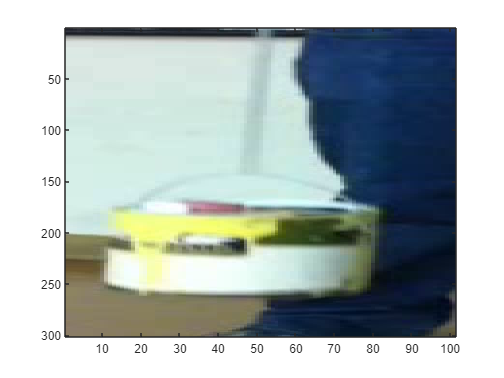

width_2 = 250:350;
height_2 = 100:400;
croppedFrame_2 = camData_2.vidFrames2_1(height_2,width_2,:,frame_2);
camImageCropped_2 = image(croppedFrame_2);

### Finds and plots X and Y for camera 2 (using initial position)

%%% Finds and plots X and Y for camera 2
width_2 = 250:350;
height_2 = 100:400;
x_2 = 26;
y_2 = 126;
d1_2 = 10;

[X_21,Y_21] = getXY(camData_2.vidFrames2_1,width_2,height_2,x_2,y_2,d1_2)

X_21 =    32.9947   32.9664   33.7093   33.9167   34.2290   31.7506   31.3815   30.5000   28.7018   27.6254   28.7439   28.4339   29.3571   30.7886   31.3639   32.0475   31.5742   31.1862   31.8039   32.1872   31.8865   32.1805   29.2607   28.1328   25.7422   22.7982   22.1211   20.6933   19.4464   18.9096   19.9817   20.1317   18.9760   20.7771   21.8810   22.1095   22.9442   24.8534   26.3515   26.5532   26.7912   26.8346   25.9923   30.2958   33.0636   32.0748   31.6976   30.7519   32.4040   32.8101


Y_21 =    68.4754   68.4336   76.4186   86.8201   98.6332  118.8226  118.9576  134.5279  154.4982  165.6942  182.7333  182.6102  202.6345  206.5363  219.8521  223.1175  222.9757  229.3644  234.8838  233.6454  230.6631  230.6209  226.5845  217.1055  218.1211  218.3165  222.8526  204.5153  189.7679  169.0847  159.0671  158.4072  122.7520  101.2452   85.8584   71.0976   70.0215   63.1888   60.8689   64.1955   69.7088   69.4788   74.1663   85.9604   98.4733  111.7855  111.2854  127.9073  148.2323  165.1899


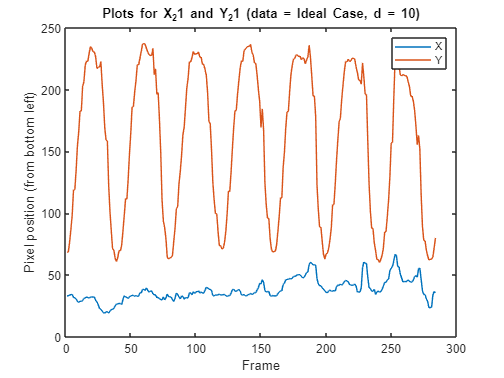


plotXY(X_21,Y_21,d1_2,Dataset)

### Finds and plots X and Y for camera 2 (using brightness)

%%% Finds and plots X and Y for camera 2
width_2 = 250:350;
height_2 = 100:400;
d2_2 = 50;

[X_22,Y_22] = getXYBright(camData_2.vidFrames2_1,width_2,height_2,d2_2)

X_22 =    45.8068   45.8065   46.3654   46.2107   46.4886   47.5919   47.4414   47.7031   46.6992   47.8225   47.9811   48.0124   48.0737   46.9979   46.9162   47.0742   46.7694   46.4228   47.5635   46.5807   46.6352   46.6544   47.6721   49.4696   48.8874   48.4432   48.3998   49.4726   49.8229   50.4867   49.5925   49.5897   49.2046   49.4414   48.6030   47.8630   47.9189   47.8662   47.8493   47.6653   48.4729   48.4837   48.3394   48.8227   48.3771   48.8181   48.7587   49.4656   49.7339   48.7199


Y_22 =   173.0921  173.0626  174.0364  176.3312  178.9742  179.9062  180.0817  182.1309  181.4291  177.7863  176.9902  176.9307  175.1554  174.8284  172.5821  171.9268  172.0369  172.6202  171.2729  171.7353  171.7787  171.8842  170.5314  170.3872  172.0298  174.7269  174.7841  177.2478  180.8975  184.5212  183.9471  183.8483  180.7285  176.7817  174.5098  172.7449  172.4079  170.8811  170.2459  171.7816  173.8590  173.7980  175.5723  178.5235  181.8006  183.3600  183.4107  184.2005  185.3825  184.0331


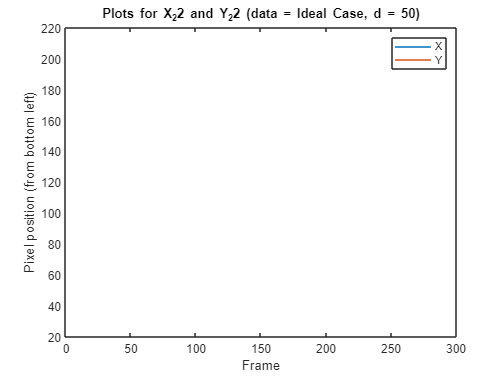


plotXY(X_22,Y_22,d2_2,Dataset)

## Camera 3

### Import data

%%% Imports data from third camera
Camera_3 = 'cam3_1.mat';

camData_3 = importCamData(Dataset,Camera_3);


### Shows uncropped and cropped frame in colour

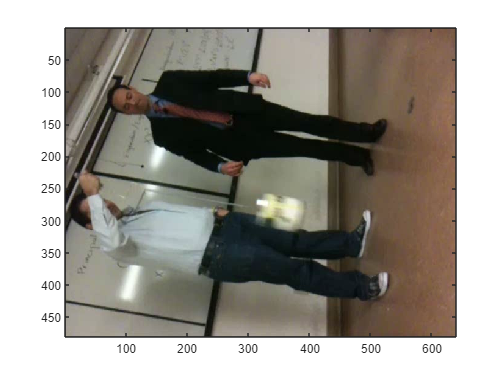

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_3 = 1;

camImage_3 = image(camData_3.vidFrames3_1(:,:,:,frame_3));

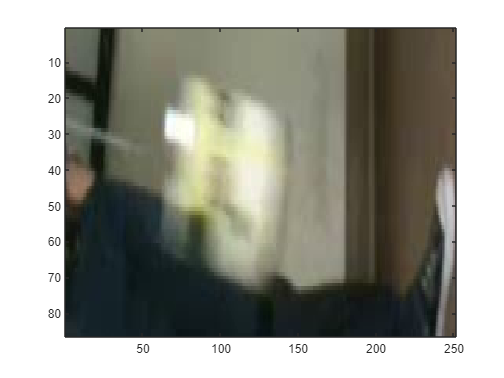

width_3 = 250:500;
height_3 = 245:330;
croppedFrame_3 = camData_3.vidFrames3_1(height_3,width_3,:,frame_3);
camImageCropped_3 = image(croppedFrame_3);

### Finds and plots X and Y for camera 3 (using initial position)

%%% Finds and plots X and Y for camera 3
width_3 = 250:500;
height_3 = 245:330;
x_3 = 73;
y_3 = 59;
d1_3 = 10;

[X_31,Y_31] = getXY(camData_3.vidFrames3_1,width_3,height_3,x_3,y_3,d1_3)

X_31 =    75.2976   75.2976   59.7632   59.9718   48.2745   48.2941   39.2075   34.7222   34.7000   35.7826   36.0000   44.4773   46.7941   50.2759   63.0870   63.4286   79.5333   80.7838   97.2333   98.3793  116.4000  131.2500  131.8000  144.6667  144.5686  155.3415  154.9556  162.5000  172.8333  174.6522  163.7037  163.7037  160.9825  157.0943  144.6491  132.3108  134.0469  119.8906  119.1270  107.1059  109.6515   86.9091   72.0328   75.0597   63.8413   62.4737   62.2037   63.5926   62.4839   50.7727


Y_31 =    57.0595   57.0595   60.9342   60.9296   63.6078   63.5294   65.2453   67.1111   67.0500   67.0870   67.0952   65.1136   64.0000   65.1552   63.7826   63.4898   61.6667   61.2162   59.6667   59.3103   58.1500   56.5357   56.5818   53.9608   54.1176   52.4634   52.9111   51.0938   47.2778   46.6087   50.0370   50.0370   50.2105   51.5849   53.8070   55.0676   54.5156   56.7812   57.0317   57.8706   57.4091   63.1061   64.9836   64.0448   66.2698   66.7368   66.3704   65.8889   65.3548   69.2727


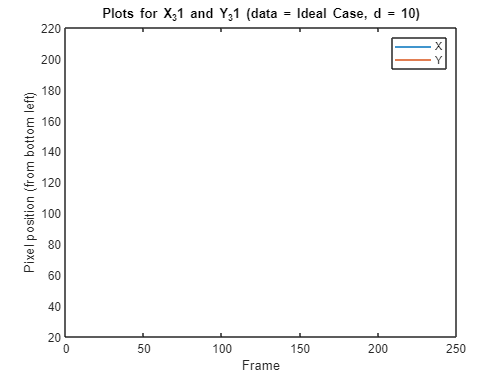


plotXY(X_31,Y_31,d1_3,Dataset)

### Finds and plots X and Y for camera 3 (using brightness)

%%% Finds and plots X and Y for camera 3
width_3 = 250:500;
height_3 = 245:330;
d2_3 = 50;

[X_32,Y_32] = getXYBright(camData_3.vidFrames3_1,width_3,height_3,d2_3)

X_32 =   155.6123  155.6240  155.9327  156.0936  152.2611  152.3017  152.4402  151.6357  151.6364  152.7075  152.7307  152.5179  152.5951  153.2298  158.4088  158.3097  156.8622  156.8913  153.4860  153.6711  149.1039  141.7279  141.4418  134.6967  134.6278  128.4638  128.3488  126.9268  125.8836  125.7405  126.3776  126.3709  128.8842  128.7520  136.3027  142.6304  142.6504  149.9065  150.1706  155.0598  155.0872  159.0237  160.3650  160.2879  157.0223  156.8621  155.3726  155.6894  155.9864  154.8790


Y_32 =    50.1292   50.1333   50.4762   50.3832   50.1923   50.1998   50.2141   50.4046   50.4003   50.4593   50.4285   50.2247   50.1951   50.3911   51.1836   51.1979   51.6999   51.6743   52.3097   52.3113   52.8576   53.9761   54.0519   54.4286   54.3953   55.4799   55.4832   55.0305   54.5418   54.5614   54.8059   54.7784   54.7005   54.7867   53.7733   53.0242   53.1510   52.6397   52.5354   51.9023   51.8596   51.6620   51.1108   51.0775   51.0066   50.9878   50.8601   50.9665   50.7666   51.0616


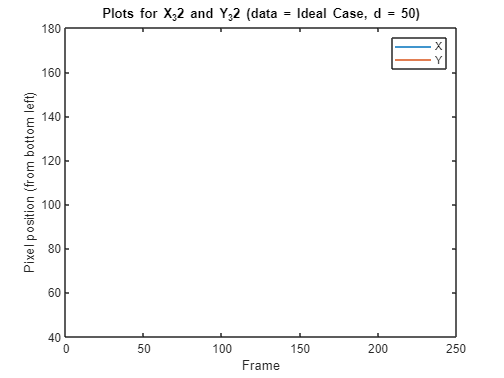


plotXY(X_32,Y_32,d2_3,Dataset)

## PCA

### Merge cameras' X and Y data

sz = min( [size(X_11,2), size(X_21,2), size(X_31,2)] )

sz = 226


X = cat( 1,X_11(1:sz),Y_11(1:sz),X_21(1:sz),Y_21(1:sz),X_31(1:sz),Y_31(1:sz) )

X =    51.9483   51.9776   52.5358   52.3875   52.3679   52.3087   52.3679   52.3087   53.3088   53.3887   53.3810   54.8036   54.7981   54.0408   54.1145   51.8467   52.7738   52.7996   52.7543   52.8073   53.2824   53.2221   53.5518   52.9817   52.9035   53.0894   52.8658   52.3127   52.3912   52.7687   51.7176   51.7828   52.5224   52.4334   52.3676   52.2697   51.9071   51.4311   51.4909   50.6768   50.6937   51.6508   51.5398   52.1563   52.8641   53.0574   51.8717   51.7081   52.0643   51.9291
  170.4417  170.4552  170.4759  170.4551  170.4432  170.4159  170.4432  170.4159  173.1658  172.3810  172.4150  171.2095  171.1370  163.2556  163.3344  155.3196  146.4852  146.5912  137.2317  137.4267  127.9432  127.7112  118.0657  106.0033  105.6930   98.8317   98.3176   92.7013   92.9675   91.5764   91.4878   91.8592   99.3178   99.1377  107.3892  107.2946  115.5731  126.4742  126.2424  134.9650  134.7717  146.4249  146.4821  154.3854  162.8454  162.9820  168.6539  168.4962  170.1522  170

### Do PCA on the data matrix (using SVD decomposition)

[~,Y,lambda] = pca(X.')

Y =   -92.0359  -39.7343    6.6681   -6.5083    1.0244    0.8772
  -92.1093  -40.1385    6.4565   -6.3162    1.0267    0.9368
  -85.5627  -49.4590    2.1824   -3.1462   -1.0089    0.9678
  -75.2859  -50.6619    1.8937   -3.0326   -1.0069    0.7878
  -64.3107  -60.0144   -2.8409   -0.6525   -2.7948   -0.0821
  -46.7680  -61.7126   -4.8916   -2.0698   -1.9739   -0.6250
  -47.3859  -66.9931   -7.4226    0.5780   -2.3546   -0.3091
  -31.4849  -66.6575   -7.6812   -0.8601   -1.5897   -0.5582
  -13.8950  -70.3593   -8.0527   -3.5922   -0.7636   -0.0211
    0.6607  -70.0716   -8.5503   -4.1720   -0.7740   -0.2033


lambda = 	1.0e+03 *

    3.5035
    2.6514
    0.0416
    0.0141
    0.0066
    0.0020


Y = Y.'

Y =   -92.0359  -92.1093  -85.5627  -75.2859  -64.3107  -46.7680  -47.3859  -31.4849  -13.8950    0.6607   14.5962   14.6664   28.7095   41.0577   52.8599   60.3556   62.0764   67.1768   71.0043   70.2688   71.7190   73.6123   68.8174   62.0976   52.7400   39.7926   39.9774   24.7466    7.9542   -8.0301  -25.8385  -25.7609  -42.8007  -57.8484  -72.8635  -83.7054  -83.9224  -91.8254  -93.2697  -92.9323  -88.5658  -90.6638  -85.0419  -74.7301  -64.1873  -49.9030  -50.5276  -35.1760  -17.9897   -2.6459
  -39.7343  -40.1385  -49.4590  -50.6619  -60.0144  -61.7126  -66.9931  -66.6575  -70.3593  -70.0716  -71.5107  -69.9420  -71.6614  -64.5451  -56.4182  -53.7994  -36.0699  -36.0856  -18.9267  -19.3897    3.1725   18.5747   24.0221   46.1911   46.6783   62.3326   62.8457   76.0551   82.3347   84.2978   82.9870   82.8636   73.1111   74.6417   57.1577   44.7431   39.9002   20.4959   20.8467    1.8999    1.7976  -17.3719  -27.0476  -31.9817  -45.4597  -46.7888  -52.2651  -53.8715  -57.0860  -58

### Plot PCA components 

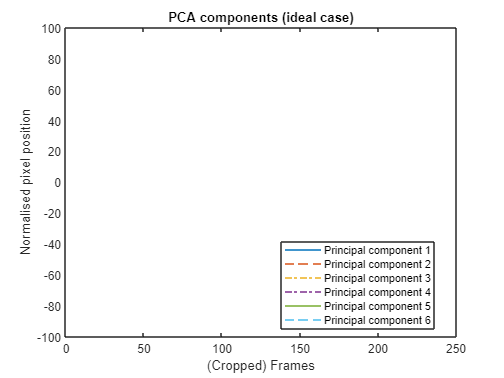

plot(Y(1,:))
title('PCA components (ideal case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')

hold on
plot(Y(2,:),'--')
plot(Y(3,:),'-.')
plot(Y(4,:),'-.')
plot(Y(5,:),'-')
plot(Y(6,:),'--')
legend('Principal component 1', ...
       'Principal component 2', ...
       'Principal component 3', ...
       'Principal component 4', ...
       'Principal component 5', ...
       'Principal component 6','Location','best')
hold off

### Plots PCA eigenvalues

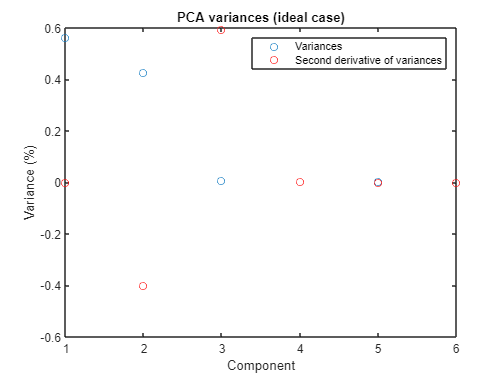

plot(lambda/sum(lambda), 'o')
title('PCA variances (ideal case)')
xlabel('Component')
ylabel('Variance (%)')

ddlambda = zeros(size(lambda));
for i = 1:length(lambda)
    if i == 1
        ddlambda(i) = 0;
    elseif i == length(lambda)
        ddlambda(i) = 0;
    else
        ddlambda(i) = (lambda(i+1) - 2*lambda(i) + lambda(i-1));
    end
end

hold on
plot(ddlambda/sum(abs(ddlambda)), 'ro')
legend('Variances','Second derivative of variances')
hold off

## Analysis

### Gets fast fourier transforms of largest principal components 

%%% Modified from fft documentation

Fs = 1;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = sz;             % Length of signal
t = (0:L-1)*T;        % Time vector

f_1 = fft(Y(1,:))

f_1 = 	1.0e+03 *

  -0.0000 + 0.0000i   0.4245 + 0.6858i   0.1967 - 0.3108i   0.6618 - 0.4488i   1.0854 - 1.3118i   2.2320 - 3.2297i  -4.2290 + 6.4205i  -1.0798 + 1.6600i  -0.6448 + 1.0534i  -0.4632 + 0.8510i  -0.3710 + 0.5364i  -0.1821 - 0.0866i  -0.1093 + 0.7063i  -0.1889 + 0.5109i  -0.2164 + 0.4367i  -0.2258 + 0.3579i  -0.1226 + 0.3440i  -0.0406 + 0.3018i  -0.1400 + 0.3464i  -0.1311 + 0.3086i  -0.1614 + 0.1996i  -0.0796 + 0.2264i  -0.0428 + 0.2478i  -0.1004 + 0.2646i  -0.1342 + 0.1597i  -0.1194 + 0.1985i  -0.0592 + 0.1944i  -0.0709 + 0.2001i  -0.0822 + 0.1953i  -0.0625 + 0.1568i  -0.0940 + 0.1407i  -0.0739 + 0.1543i  -0.0527 + 0.1210i  -0.0890 + 0.1672i  -0.1237 + 0.1491i  -0.0715 + 0.1116i  -0.0664 + 0.0850i  -0.1069 + 0.0628i  -0.1022 + 0.1137i  -0.0132 + 0.0776i  -0.1404 + 0.3477i  -0.0562 + 0.1808i  -0.0453 + 0.1016i  -0.0860 + 0.1111i  -0.0692 + 0.1200i  -0.0553 + 0.1297i  -0.0628 + 0.0946i  -0.0946 + 0.1121i  -0.0895 + 0.1049i  -0.0427 + 0.1120i


f_2 = fft(Y(2,:))

f_2 = 	1.0e+03 *

   0.0000 + 0.0000i  -1.1308 - 0.1791i  -0.9269 - 0.1807i  -1.2210 - 0.1582i  -1.6347 - 0.2422i  -3.3753 - 1.8559i   5.1852 + 3.6970i   1.2117 + 0.9650i   0.7399 + 0.5976i   0.3991 + 0.4036i   0.3350 + 0.4320i  -0.0448 + 0.0087i  -0.0312 + 0.5466i   0.0592 + 0.2945i   0.0625 + 0.3084i   0.0304 + 0.2565i   0.0486 + 0.2401i  -0.0168 + 0.2166i  -0.0217 + 0.2016i  -0.0167 + 0.1889i  -0.0190 + 0.2014i   0.0098 + 0.1833i  -0.0343 + 0.1569i   0.0083 + 0.1600i   0.0030 + 0.1051i  -0.0554 + 0.1160i  -0.0392 + 0.1004i   0.0428 + 0.2507i   0.0095 + 0.1290i  -0.0123 + 0.1483i  -0.0181 + 0.0900i  -0.0273 + 0.1094i  -0.0305 + 0.0829i  -0.0309 + 0.1009i  -0.0200 + 0.0758i  -0.0668 + 0.1042i  -0.0548 + 0.0959i  -0.0378 + 0.0928i  -0.1073 + 0.1580i  -0.0459 + 0.1150i  -0.0179 + 0.0688i  -0.0438 + 0.0772i  -0.0571 + 0.0984i  -0.0270 + 0.0502i  -0.0904 + 0.0622i  -0.0475 + 0.0750i  -0.0515 + 0.0680i  -0.0597 + 0.0569i  -0.0323 + 0.0515i  -0.0363 + 0.0817i


### Plot absolute values of the FFT

#### PC1

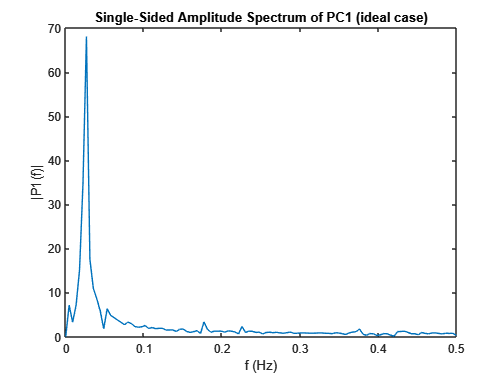

%%% Modified from fft documentation

P2_1 = abs(f_1/L);
P1_1 = P2_1(1:L/2+1);
P1_1(2:end-1) = 2*P1_1(2:end-1);

f1 = Fs*(0:(L/2))/L;
plot(f1,P1_1) 
title('Single-Sided Amplitude Spectrum of PC1 (ideal case)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


P1_1_max = max(P1_1)

P1_1_max = 68.0361

f1_max = f1(P1_1 == P1_1_max)

f1_max = 0.0265

### Use least square fitting to estimate sine waves for PCs (assuming simple harmonic motion)

#### PC1

%%% Minimise LSE: sum( abs( f(x_k)-y_k )^2 )
%%% Function: f(x) = A*sin(omega_n*x + phi)
x = 1:sz;
LSE_sin_1 = @(n) sum( abs( n(1)*sin(n(2)*x + n(3))-Y(1,:) ).^2 );
n0_1 = [P1_1_max, f1_max*2*pi, 0*(pi/180)];
coef_1 = fminsearch(LSE_sin_1,n0_1)

coef_1 =   -82.1503    0.1572    1.5253


Error_1 = LSE_sin_1(coef_1)

Error_1 = 1.6542e+04

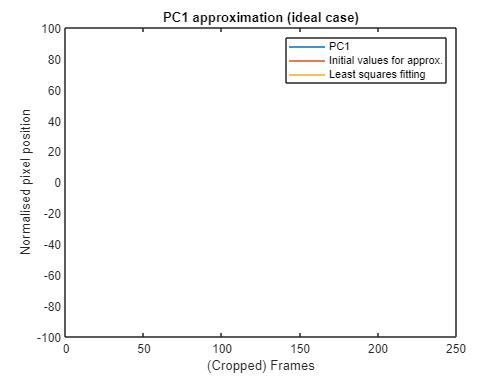


y_1 = coef_1(1)*sin(coef_1(2)*x + coef_1(3));
y0_1 = n0_1(1)*sin(n0_1(2)*x + n0_1(3));

plot(Y(1,:))
title('PC1 approximation (ideal case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_1)
plot(y_1)
legend('PC1','Initial values for approx.', 'Least squares fitting')
hold off

## Various functions are here:

### Imports data

function camData = importCamData(Dataset,Camera)

Data_path =join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\OneDrive - University College London' ... 
    '\Project Datasets' ...
    '\',Dataset, ... 
    '\',Camera] ); % Change to location of files

camData = load( Data_path );

end



### Shows cropped and uncropped video frame

%%% Shows cropped and uncropped video frame
function [im_1,im_2] = showFrames(frameNum,vidFrame,width,height)

normFrame = vidFrame(:,:,:,frameNum);
im_1 = image(normFrame);

croppedFrame = vidFrame(height,width,:,frameNum);
im_2 = image(croppedFrame);

end



### Finds pixel that corresponds to cap

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d)

if nargin == 4
    d = 10;
elseif nargin == 2
    x = 82;
    y = 198;
end


r = croppedFrame1(end-y,x,1);
g = croppedFrame1(end-y,x,2);
b = croppedFrame1(end-y,x,3);


cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));
end



### Finds the pixels that correspond to the cap using brightness

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixelsBright(croppedFrame,d)

if nargin == 1
    d = 10;
end

br = max( rgb2gray(croppedFrame) );

cap_Pixels = ((croppedFrame(:,:,1) >= br - d) & (croppedFrame(:,:,1) <= br + d)) ...
            &((croppedFrame(:,:,2) >= br - d) & (croppedFrame(:,:,2) <= br + d)) ...
            &((croppedFrame(:,:,3) >= br - d) & (croppedFrame(:,:,3) <= br + d));
end

### Finds the bounds for the cap pixels

%%% Finds the bounds for the cap pixels
function [top,bottom,left,right] = Boundaries(cap_Pixels)

top = 0;
bottom = 0;
left = 0;
right = 0;

sz_row = size(cap_Pixels,1);
for i = 1:sz_row
    findOne = size(find(cap_Pixels(i,:)));
    if findOne(2) ~= 0
        top = sz_row - i;
        break;
    end
end

for i = 1:sz_row
    findOne = size(find(cap_Pixels(end-i,:)));
    if findOne(2) ~= 0
        bottom = i;
        break;
    end
end

sz_col = size(cap_Pixels,2);
for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,i)));
    if findOne(1) ~= 0
        left = i;
        break;
    end
end

for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,end-i)));
    if findOne(1) ~= 0
        right = sz_col - i;
        break;
    end
end

end



### Finds centre from bounds

%%% Finds centre from bounds
function [x,y] = centre(top,bottom,left,right)

y = mean([top,bottom]);
x = mean([left,right]);

end



### Finds centre from averaging the number of pixels

%%% Finds centre from averaging the number of pixels
function [x,y] = centre_avg(cap_Pixels)
[sz_row,sz_col] = size(cap_Pixels);

x = 0;
x_num = 0;
for i = 1:sz_col
    x = x + sum(cap_Pixels(:,i))*i ;
    x_num = x_num + sum(cap_Pixels(:,i)) ;
end
x = x/x_num;

y = 0;
y_num = 0;
for i = 1:sz_row
    y = y + sum(cap_Pixels(i,:))*i ;
    y_num = y_num + sum(cap_Pixels(i,:)) ;
end
y = sz_row - y/y_num;

end



### Gets X and Y data from camera data

%%% Gets X and Y data from camera data
function [X,Y] = getXY(camData,width,height,x,y,d)

if nargin == 5
    d = 10;
elseif nargin == 3
    x = 82;
    y = 198;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);
croppedFrame1 = camData(height,width,:,1);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Gets X and Y data from camera data using brightness

%%% Gets X and Y data from camera data
function [X,Y] = getXYBright(camData,width,height,d)

if nargin == 3
    d = 10;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixelsBright(croppedFrame,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Plots X and Y on the same graph

%%% Plots X and Y on the same graph
function plotXY(X,Y,d,Dataset)

plot(X)
if nargin == 4
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (data = ',Dataset,', d = ',num2str(d),')']);
else
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (d = ',num2str(d),')']);
end
title(title_text)
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y)
legend('X','Y')
hold off

end



